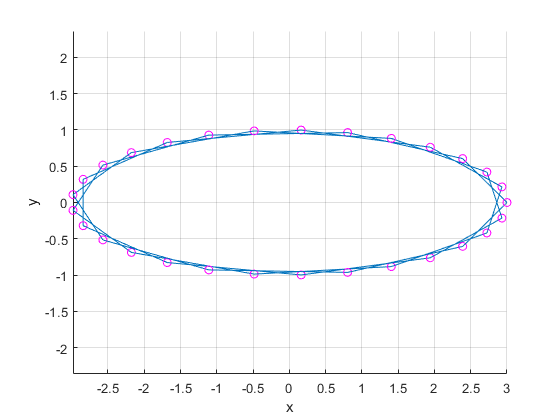

clear
clc 
close all

%3D Lines:
t = linspace(0, 6*pi, 30);
x = 3*cos(t);
y = 1*sin(t);
z = 0.01*t.^2;

figure
hold on
plot3(x,y,z)
plot3(x,y,z,'mo')
xlabel('x')
ylabel('y')
zlabel('z')
grid on
axis('equal')

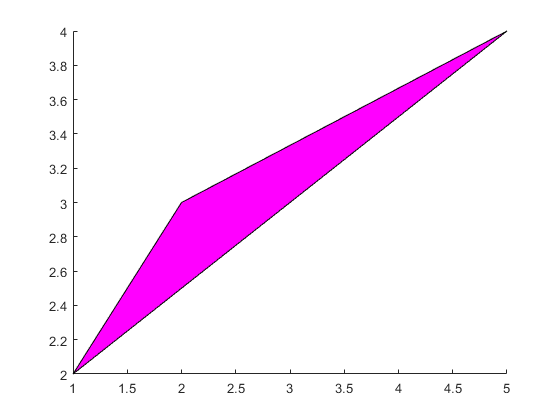


%3D Surfaces:
%{
To draw 3D surfaces, we can evaluate the function at a series of points,
and use these as vertices to draw primitives which will form the surface.
The patch function allows us to supply points and it will draw the
primitives:
patch:
%}

x = [1 2 5];
y = [2 3 4];
z = [1 3 0];

figure
patch(x, y, z, 'm');

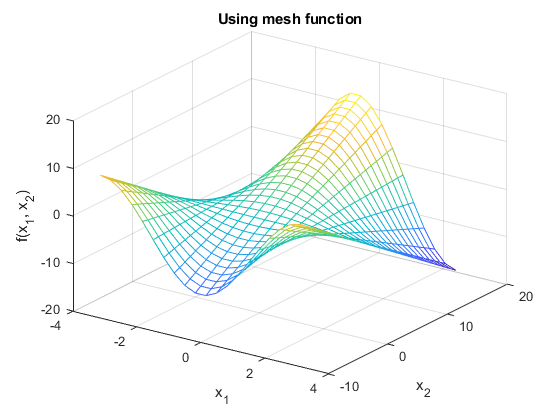


%{
mesh and meshgrid:
The meshgrid function effectively computes the cartesian product of the
two inputs (i.e. A x B in set theory). This gives us all possible
combinations of the two inputs. We can then evaluate the function at each
of these points, and use the mesh or surf function to plot the surface.
The mesh function plots a wireframe mesh whereas the surf function colours
the mesh:
%}

x1 = linspace(-pi, pi, 20);
x2 = linspace(-10, 16, 30);

[X1, X2] = meshgrid(x1, x2); %create cartesian product

Z = cos(X1).*X2; %evaluate function at each point in cartesian product

figure
mesh(X1, X2, Z); %use mesh function to plot mesh
xlabel('x_1')
ylabel('x_2')
zlabel('f(x_1, x_2)')
grid on
title('Using mesh function')
view([35 30]) %give default viewpoint for plot

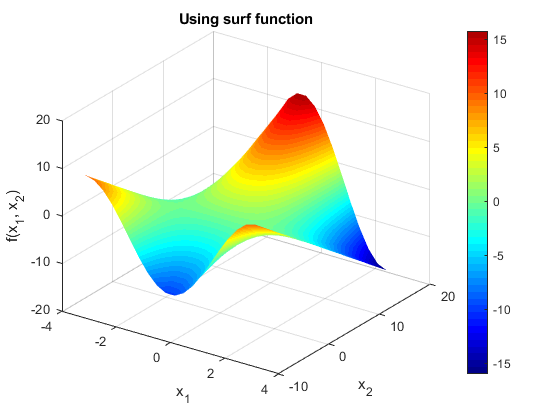


%surf function:
figure
surf(X1, X2, Z); %use surf function to plot mesh
xlabel('x_1')
ylabel('x_2')
zlabel('f(x_1, x_2)')
grid on
title('Using surf function')
view([35 30])
shading interp %removes wireframe black lines
colorbar %adds a legend for colours
colormap(jet(50)) %change colormap

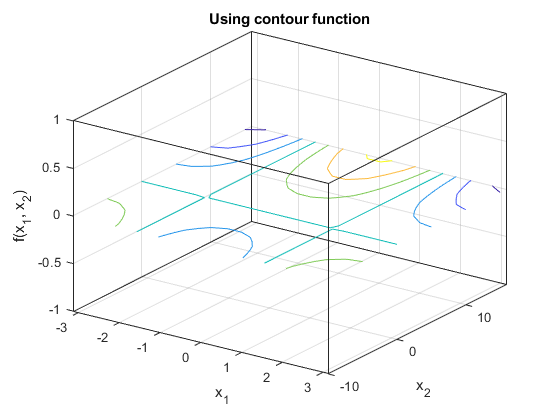


%contour
figure
contour(X1, X2, Z);
xlabel('x_1')
ylabel('x_2')
zlabel('f(x_1, x_2)')
grid on
title('Using contour function')
view([35 30])

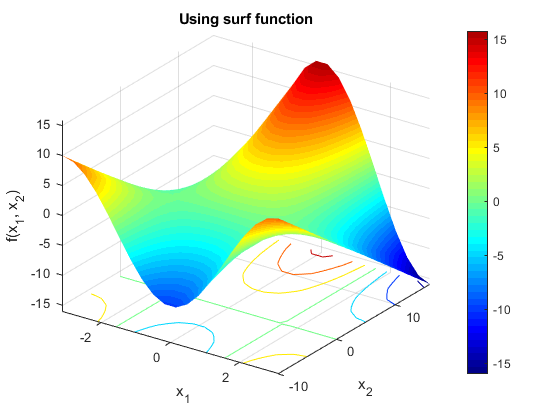


%surf function - combination of surf and contour:
figure
surfc(X1, X2, Z); %use surfc function to plot mesh
xlabel('x_1')
ylabel('x_2')
zlabel('f(x_1, x_2)')
grid on
title('Using surf function')
view([35 30])
shading interp
colorbar 
colormap(jet(50))

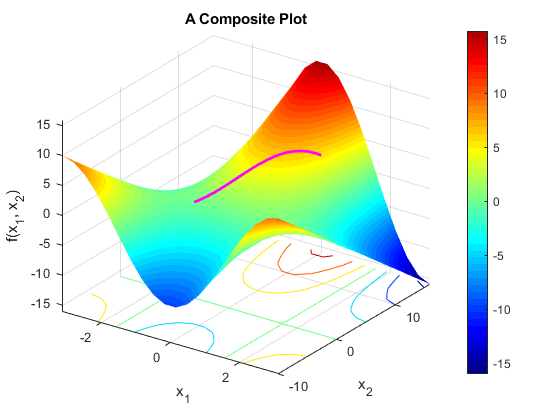


%Make a composite plot:
x1_line = linspace(-1, 1, 20);
x2_line = linspace(0, 10, 20);
z_line = cos(x1_line).*x2_line;

figure
hold on
surfc(X1, X2, Z); %use surfc function to plot mesh
plot3(x1_line, x2_line, z_line, 'm', 'LineWidth', 2);
xlabel('x_1')
ylabel('x_2')
zlabel('f(x_1, x_2)')
grid on
title('A Composite Plot')
view([35 30])
shading interp
colorbar 
colormap(jet(50))

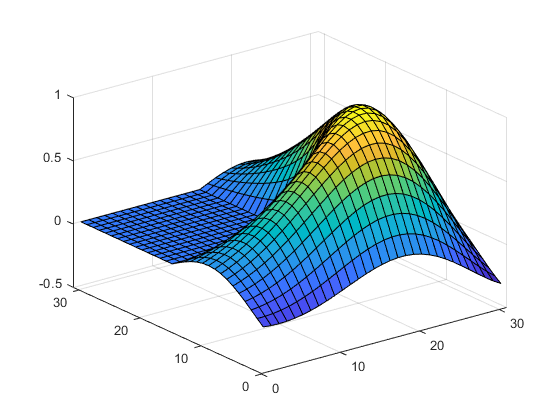


%Generate the Matlab logo
%L = 160*membrane(1,100);
L = membrane(1);
L2 = membrane(2);
figure
surf(L);

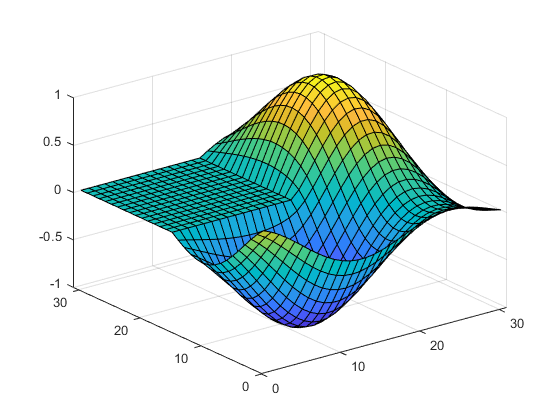

surf(L2);